Proportion of significant modes in a group

clear all
close all

addpath('/home/trangc/kg98/trangc/library/Violinplot-Matlab-master')
diagString = {'HC', 'BD', 'SCA',...
    'SCZ', 'ASD', 'MDD' };
plotOrder = [5, 2, 6, 3, 4]; %to match with plot in vbm
load('corr_MBM.mat');

nSite = length(map.numericFolders);


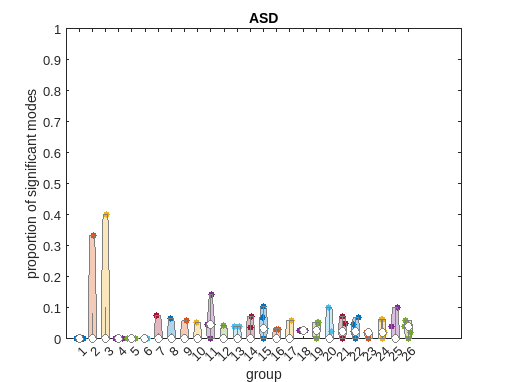

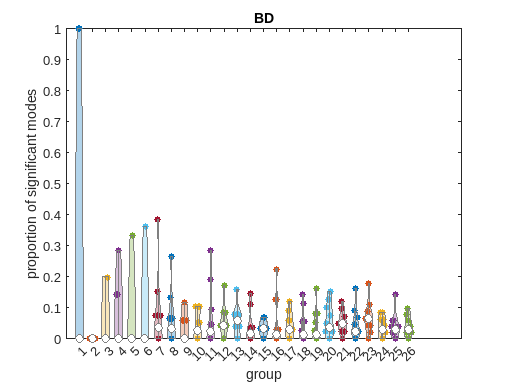

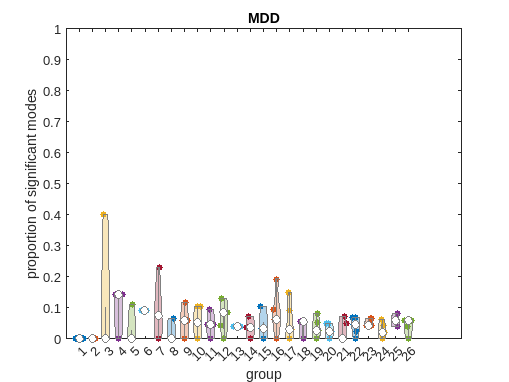

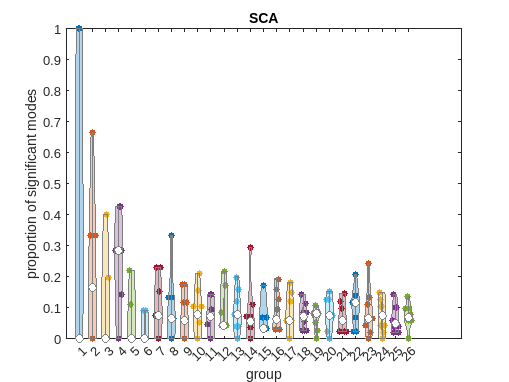

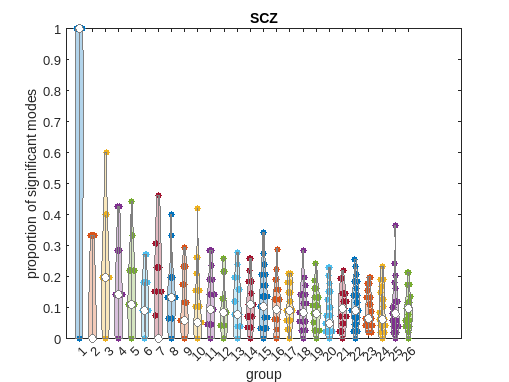

iGroup = 0:25;
nPerGroup = (2*iGroup+1);
maxInGroup = cumsum(nPerGroup);
minInGroup = [1, maxInGroup(1:end-1)+1];

for iDiag = plotOrder
    isDiagSite = strcmp(map.diag, num2str(iDiag));
    for iNE = 1:length(maxInGroup)
     
        corToPlot (:,iNE) =  (sum(map.betaThres(isDiagSite,minInGroup(iNE):maxInGroup(iNE)),2)'./nPerGroup(iNE));

    end
    fig = figure('Position', [200 200 800 600]);
    violinplot(corToPlot, cellfun(@num2str, num2cell(iGroup+1), 'UniformOutput', false));
    xlabel('group')
    ylabel('proportion of significant modes')
ylim([0 1])
    title(diagString(iDiag))

    xticklabels(iGroup+1)

    clear corToPlot

end